# ECEN 5463 | Final Project

Collin Thornton

## Nonlinear Control of Quadrotor for Point Tracking: Actual Implementation and Experimental Tests

Paper found @ https://ieeexplore-ieee-org.argo.library.okstate.edu/stamp/stamp.jsp?tp=&arnumber=6844882

This paper implements an integral backstepping in order to solve he trajectory tracking of the QBall2 quadrotor.

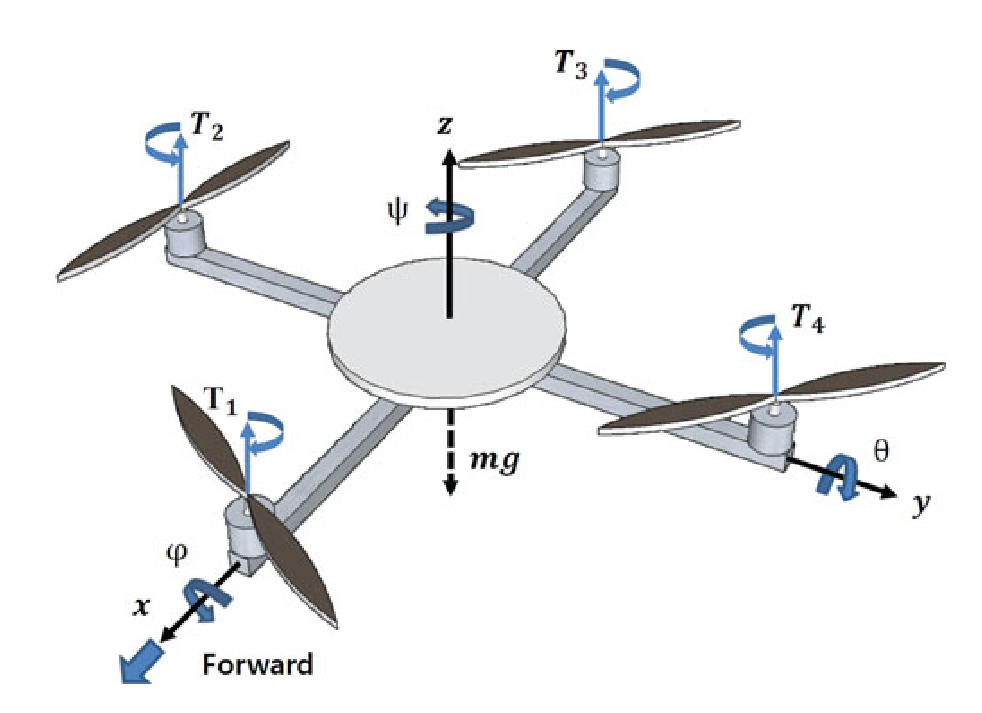

Notation:

$\phi \to \textrm{roll}$,  $\theta \to \textrm{pitch}$, and $\psi \to \textrm{yaw}$

Nonlinear mathematical model of the quadrotor:


$$\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} \\
\ddot{z} \\
\ddot{\phi} \\
\ddot{\theta} \\
\ddot{\psi} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{U_1 }{m}\left(\cos \left(\phi \right)\sin \left(\theta \right)\cos \left(\psi \right)+\sin \left(\phi \right)\sin \left(\psi \right)\right)\\
\frac{U_1 }{m}\left(\cos \left(\phi \right)\sin \left(\theta \right)\sin \left(\psi \right)-\sin \left(\phi \right)\cos \left(\psi \right)\right)\\
\frac{U_1 }{m}\left(\cos \left(\phi \right)\cos \left(\theta \right)\right)-g\\
\frac{{\mathrm{lU}}_2 +\dot{\theta} \dot{\psi} \left(I_y -I_z \right)-J_r \dot{\theta} \Omega }{I_x }\\
\frac{{\mathrm{lU}}_3 +\dot{\phi} \dot{\psi} \left(I_z -I_x \right)+J_r \dot{\phi} \Omega }{I_y }\\
\frac{U_4 +\dot{\phi} \dot{\theta} \left(I_x -I_y \right)}{I_z }
\end{array}\right\rbrack$$


Parameters:


$$m\to \textrm{mass}$$



$$g\to \textrm{gravity}\;\left(\textrm{acceleration}\right)$$



$$l\to \mathrm{distance}\;\mathrm{from}\;\mathrm{COG}\;\mathrm{of}\;\mathrm{quadrotor}\;\mathrm{and}\;\mathrm{center}\;\mathrm{of}\;\mathrm{propeller}$$



$$I_{x,y,z} \to \mathrm{moments}\;\mathrm{of}\;\mathrm{inertia}$$



$$J_r \to \mathrm{moment}\;\mathrm{of}\;\mathrm{inertia}\;\mathrm{of}\;\mathrm{the}\;\mathrm{motor}$$



$$\Omega \to \omega_1 -\omega_2 +\omega_3 -\omega_4$$



$$U_1 \to \mathrm{Total}\;\mathrm{motor}\;\mathrm{thrust}$$



$$U_2 \to \textrm{Roll}\;\textrm{torque}$$



$$U_3 \to \textrm{Pitch}\;\textrm{torque}$$



$$U_4 \to \mathrm{Yaw}\;\mathrm{torque}$$


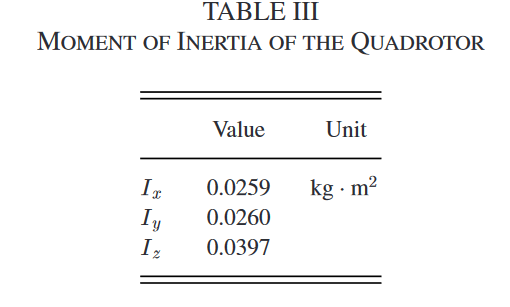


$$\left\lbrack \begin{array}{c}
U_1 \\
U_2 \\
U_3 \\
U_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sum_{i=1}^4 T_i \\
T_3 -T_4 \\
T_2 -T_1 \\
Q_1 +Q_2 -Q_3 -Q_4 
\end{array}\right\rbrack$$


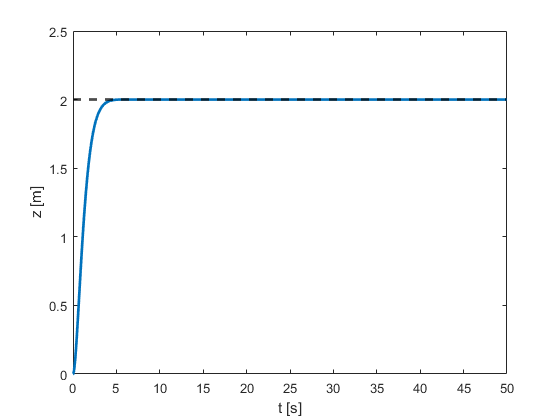

clearvars;

p.traj = @(t) traj(t);
p.m = 1.336;
p.g = 9.80665;
p.l = 0.285;
p.Ix = 0.0259;
p.Iy = 0.0260;
p.Iz = 0.0397;
p.Omega = 0;
p.Jr = 0;

p.k = [2.5;2.5;2.5;2.5;2.0;2.0;2.2;0.5;0.75;0.75;0.75;0.75];

x0 = zeros(12,1);
x0(1) = deg2rad(10);
x0(3) = deg2rad(5);
x0(5) = deg2rad(10);

tspan = [0 50];

[t,x] = ode45(@(t,x) closedLoopDynamicsUAV(t,x,p), tspan, x0);

figure()
plot(t, x(:,7), "LineWidth", 2)
hold on;
xlabel("t [s]")
ylabel("z [m]")
hold on
yline(2, "--k", "LineWidth", 2)

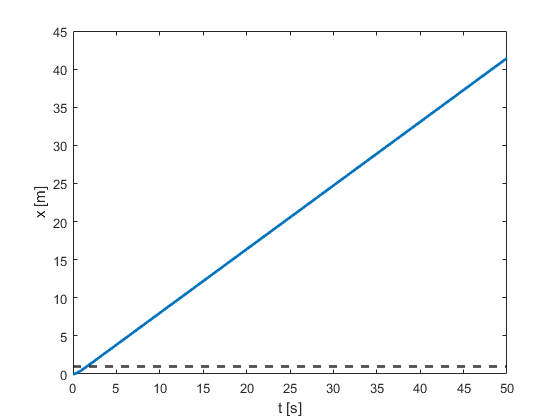

figure()
plot(t, x(:,9), "LineWidth", 2)
ylabel("x [m]")
xlabel("t [s]")
hold on
yline(1, "--k", "LineWidth", 2)

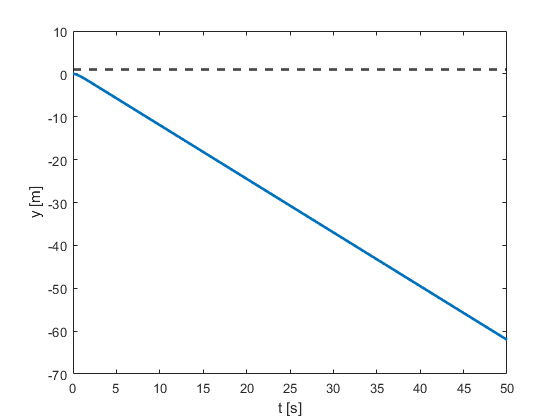

figure()
plot(t, x(:,11), "LineWidth", 2)
ylabel("y [m]")
xlabel("t [s]")
hold on
yline(1, "--k", "LineWidth", 2)

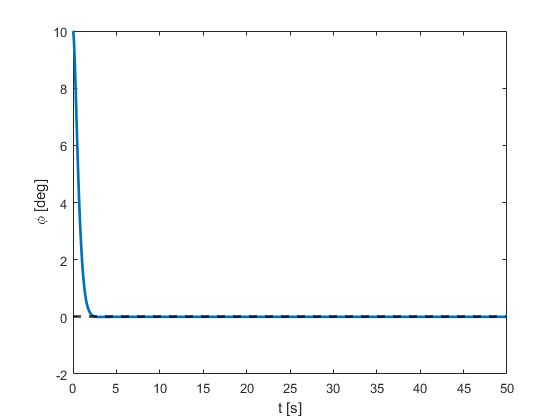

figure()
plot(t, rad2deg(x(:,1)), "LineWidth", 2)
ylabel("\phi [deg]")
xlabel("t [s]")
yline(0, "--k", "LineWidth", 2)

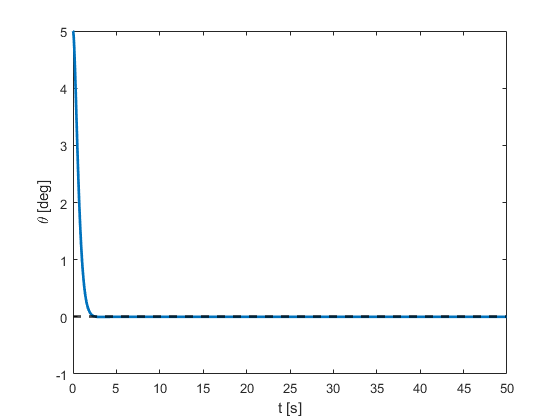

figure()
plot(t, rad2deg(x(:,3)), "LineWidth", 2)
ylabel("\theta [deg]")
xlabel("t [s]")
yline(0, "--k", "LineWidth", 2)

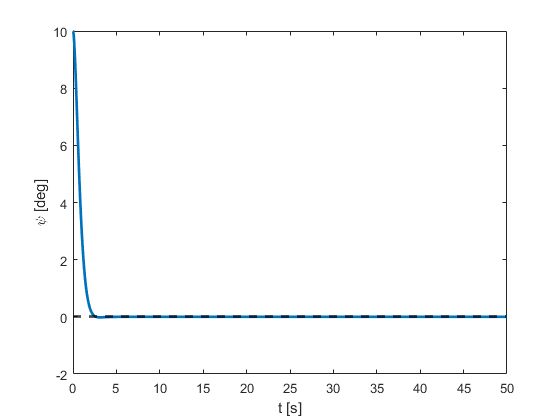

figure()
plot(t, rad2deg(x(:,5)), "LineWidth", 2)
ylabel("\psi [deg]")
xlabel("t [s]")
yline(0, "--k", "LineWidth", 2)


$$x={\left\lbrack \begin{array}{cccccccccccc}
\phi  & \dot{\phi}  & \theta  & \dot{\theta}  & \psi  & \dot{\psi}  & z & \dot{z}  & x & \dot{x}  & y & \dot{y} 
\end{array}\right\rbrack }^T$$


function [dy] = closedLoopDynamicsUAV(t, x, p)   
    dx = uavDynamics(t, x, controlUAV(t, x, p), p);
    dy = [dx];
end

function [dx] = uavDynamics(t,x,u,p)
    dx = zeros(12,1);
    dx(1:2:12) = x(2:2:12);
    
    phi = x(1); dphi = x(2);
    theta = x(3); dtheta = x(4);
    psi = x(5); dpsi = x(6);
    
    dx(2) = (p.l*u(2) + dtheta*dpsi*(p.Iy-p.Iz) - p.Jr*dtheta*0)/p.Ix;
    dx(4) = (p.l*u(3) + dphi*dpsi*(p.Iz-p.Ix) + p.Jr*dphi*0)/p.Iy;
    dx(6) = (u(4) + dphi*dtheta*(p.Ix-p.Iy))/p.Iz;
    dx(8) = u(1)/p.m*(cos(phi)*cos(theta)) - p.g;
    dx(10) = u(1)/p.m*(cos(phi)*sin(theta)*cos(psi) + sin(phi)*sin(psi));
    dx(12) = u(1)/p.m*(cos(phi)*sin(theta)*sin(psi) - sin(phi)*cos(psi));
end

function [u] = controlUAV(t, x, p)
    x0 = p.traj(t);
    e = x - x0;
    e(2:2:12) = e(2:2:12) + p.k(1:2:12).*e(1:2:12);
    
    kp = 0.05;
    gamma1 = -max(min(kp*e(10), 0.7071), -0.7071);
    gamma2 = -max(min(kp*e(12), 0.7071), -0.7071);
    
    %x0(1) = asin(gamma1*cos(x(5)) - gamma2*(sin(x(5))));
    %x0(1) = gamma1*sin(x0(5)) - gamma2*cos(x0(5));
    %x0(3) = gamma1*cos(x0(5)) + gamma2*sin(x0(5));
    
    e = x - x0;
    e(2:2:12) = e(2:2:12) + p.k(1:2:12).*e(1:2:12);
    
    
    
    u = zeros(4,1);
    u(1) = (p.m*(p.g+(p.k(7)^2-1)*e(7) - (p.k(7)+p.k(8))*e(8)))/(cos(x(1))*cos(x(3)));
    u(2) = p.Ix/p.l * (-x(4)*x(6)*(p.Iy-p.Iz)/p.Ix + p.Jr/p.Ix*x(4)*0 + (p.k(1)^2-1)*e(1) - (p.k(1)+p.k(2))*e(2));
    u(3) = p.Iy/p.l * (-x(2)*x(6)*(p.Iz-p.Ix)/p.Iy - p.Jr/p.Iy*x(2)*0 + (p.k(3)^2-1)*e(3) - (p.k(3)+p.k(4))*e(4));
    u(4) = p.Iz * (-x(2)*x(4)*(p.Ix-p.Iy)/p.Iz + (p.k(5)^2-1)*e(5) - (p.k(5)+p.k(6))*e(6));
end


function [xd] = traj(t)
    xd = [0;0; 0;0; 0;0; 2;0; 1;0; 1;0];
end